# Test 2: Two layers, elastic & lateral heterogenities

In this notebook the tidal response of a **two-layers, elastic body with lateral variations** is computed using LOV3D and compared against: 

- [Berne et al.](https://doi.org/10.1029/2022JE007712) FEM model 

- [Qiin et al.](https://doi.org/10.1093/gji/ggu279) spectral perturbation model 

The script can be used to reproduced Figure 2 of [Rovira-Navarro et al. 2023](https://arxiv.org/abs/2311.15710)

clearvars
clc
set(0,'defaulttextInterpreter','latex') 
mfile_name          = mfilename('fullpath');
if contains(mfile_name,'LiveEditorEvaluationHelper')
    mfile_name=matlab.desktop.editor.getActiveFilename;
end
[pathstr,name,ext]  = fileparts(mfile_name);
cd(pathstr);
cd('..')
addpath(genpath(pwd))

## Interior model

The interior model is based on the **Enceladus model **presented in [Rovira-Navarro et al. 2023](https://arxiv.org/abs/2311.15710). 

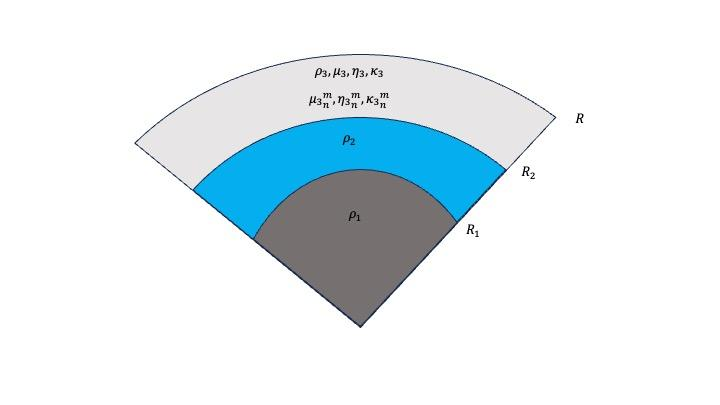

The model parameters are given in non-dimensional variables. The following non-dimensional parameters are used

mu_eff:  $\mu_{eff}=\frac{\mu_3}{g_s\bar\rho R_3}$, 

MaxTime: $\tau=\frac{\omega\eta_3}{\mu_3}$

r_ratio: $\frac{R_3}{R_1}$

rho_r: $\frac{\bar\rho_c}{\rho_3}$, where $\bar\rho_c$ is the average density of layers' 1 and 2

% MEAN VALUES 
G=6.67e-11; 
r_ratio=0.91; %ratio between R3 and R2
rho_ratio=1610/1000; %rho_av/rho_3
Ks_nd=100; %ratio between bulk modulus \kappa and shear modulus \mu  
mu_eff=3.3e9/(4/3*pi*G*252.1e3^2*1610^2); %effective shear modulus
Interior_Model.Delta_rho=0; %density jump between layer 2 and layer 3
% LATERAL VARIATIONS 
n_LV=1; % degree of lateral variations 
m_LV=0; % order of lateral variations 
% the benchmark can be done for n_LV=1, m_LV=0; n_LV=2, m_LV=0; n_LV=1 m_LV=1
% BUILD INTERIOR MODEL 
rho_r=(rho_ratio-1+r_ratio^3)/r_ratio^3;
rho_av=rho_r*r_ratio^3+(1-r_ratio^3);
Gg=3/(4*pi)/mu_eff/rho_av^2;
%Core layer (1), includes both the silicate core and ocean
Interior_Model(1).R0= r_ratio; % core boundary 
Interior_Model(1).rho0= rho_r; % mean core density  
Interior_Model(1).Delta_rho0=0; % density contrast beteen layers 2 and 3, set to 0 for the ice ocean interface
%Ice layer (2)
Interior_Model(2).R0= 1;  %surface radius
Interior_Model(2).rho0=1; %mantle density 
Interior_Model(2).Ks0=Ks_nd; %bulk modulus 
Interior_Model(2).mu0=1;  %shear modulus
Interior_Model(2).MaxTime=NaN; %nondimensional Maxwell time, elastic model assumed
Interior_Model(2).Gg=Gg; %non-dimensional gravitational constatant
Interior_Model(2).nR=n_LV; 
Interior_Model(2).mR=m_LV; 
Interior_Model(2).variable_mu_p = 0; %peak-to-peak variations of shear modulus (in %)
Interior_Model(2).variable_eta_p =0; %peak-to-peak variations of viscosity (in %)
Interior_Model(2).variable_K_p = 0; %peak-to-peak variations of bulk modulus (in %)

## Define forcing

The forcing potential is defined

T=1; % the forcing period has been normalized
Forcing(1).Td=T;
Forcing(1).n=2; 
Forcing(1).m=0; 
Forcing(1).F=1;

## Define numerics used to compute the tidal response 

%radial discretization
Numerics.Nlayers = length(Interior_Model); % number of concentric layers. Including the core!
Numerics.method = 'fixed'; % method of setting the radial points per layer
Numerics.Nrbase = 1000; % depending on the method this will determine the number of points per layer
%code parallelization
Numerics.parallel_sol = 0; % Calculate the solution using a parfor-loop either 0 or 1
Numerics.parallel_gen = 0; % Calculate potential coupling files using parfor-loops either 0 or 1
% lateral variations
Numerics.perturbation_order = 2; %maximum order to which couplings are considered
Numerics.solution_cutoff = 12; % maximum degree of solution, not used if perturbation order is specified
Numerics.load_couplings = 1; % 0=no loading, 1=loading of specific file, 2=searches for big enough file
Numerics.Nenergy = 12; % maximum degree to which energy dissipation is expanded 
Numerics.rheology_cutoff = 2; % maximum order of difference (so in log) up to which rheology is still used 
[Numerics, Interior_Model] = set_boundary_indices(Numerics, Interior_Model,'verbose');

Inside set_boundary_indices: 
Nrlayer: 0  1000
BCindices: 
Nr: 1000
 


## Load data for benchmark

The data, stored in ../data/tests/enceladus/, is loaded 

load_file_Q=['data/tests/enceladus/Q_' num2str(n_LV) num2str(m_LV) '.mat'];
load_file_B=['data/tests/enceladus/B_' num2str(n_LV) num2str(m_LV) '.mat'];
load(load_file_Q)
load(load_file_B)
% the following data is loaded 
    % k2_B; k2_Q; degree 2 Love number of the spherically-symmetric model 
    % k_Q; k_B: Love number spectra
        %kD_X(1,:): Amplitude of the perturbation in peak to peak variation of the shear modulus [in %] 
        %kD_X(2:end,1): Degree of tidal response  
        %kD_X(2:end,2): Order of tidal response 
        %kD_X(2:end,3): Perturbation order 
        %kD_X(2:end,3:end): Amplitude of the tidal response 
    % kD_Q; kD_N: is simply k-k2
% Note that only the m>0 terms are given, with the understanding that the m<0 follow from there
% Some additional variables used: 
l_max=50;
Ynm_stokes.clm=zeros(2*l_max,2*l_max);
Ynm_stokes.slm=zeros(2*l_max,2*l_max);
Ynm_stokes.lmax=2*l_max-1;
Ynm_stokes.clm(Interior_Model(2).nR+1,Interior_Model(2).mR+1)=1;
[Ynm_zlonlat] = SPH_LatLon(Ynm_stokes);
Ynm_z=Ynm_zlonlat.z;
Delta=max(Ynm_z(:))-min(Ynm_z(:));
% amplitude of lateral variations in peak to peak % variations
amp3=amp*100*Delta/sqrt(4*pi);
% amplitude of lateral variations in real spherical harmonics
if Interior_Model(2).mR==0
    amp2=amp/sqrt(4*pi); 
else
    amp2=amp/sqrt(2)/sqrt(4*pi);
end
amp_B=[1.0000    2.0000    5.0000   10.0000   16.0000   25.0000   35.0000   50.0000];
ind_B=[];
for i=1:length(amp_B)
    ind_B(i)=find(abs(amp_B(i)-amp3)/amp_B(i)<1e-4);    
end

## Compute the tidal response using LOV3D

Compute Tidal Response using LOV3D for the set of interior models specified 

% UNIFORM MODEL 
Interior_Model(2).variable_mu_p=0;
Interior_Model = get_rheology(Interior_Model,Numerics,Forcing);
[Love_Spectra,y_rad]=get_Love(Interior_Model,Forcing,Numerics);
iforcing=find(Love_Spectra.n==Forcing.n & Love_Spectra.m==Forcing.m);
k2_uniform=Love_Spectra.k(iforcing); 
% LATERAL VARIATIONS
for kk=1:length(amp2)

end

## Compare results

## Plot the results of the benchmark